clc;
clear;
close all;

%% =========================================================
%  PARAMETERS
%% =========================================================

% Lengths (cm)
r1 = 19;
r3 = 45;
r5 = 50;
r7 = 18;

% Shoulder position
Ps = [0;0;r1];

% Trocar point
Pp = [17;40;50];

% Tool-tip path
Pi = [25;75;30];
Pf = [25;83;30];

% Number of trajectory points
N = 80;

% Straight-line parameter
s = linspace(0,1,N);

% Tool tip trajectory
Pt = Pi + (Pf-Pi).*s;

%% =========================================================
%  STORAGE
%% =========================================================

Q = zeros(N,6);

Elbow_all = zeros(3,N);
Wrist_all = zeros(3,N);

%% =========================================================
%  INITIAL GUESS
%% =========================================================

X0 = [10 20 20 20 50 30 0.5];

options = optimoptions('lsqnonlin',...
    'Algorithm','levenberg-marquardt',...
    'Display','off', ...
    'MaxIterations',1000,...
    'MaxFunctionEvaluations',1e5,...
    'FunctionTolerance',1e-14,...
    'StepTolerance',1e-14,...
    'OptimalityTolerance',1e-14);

%% =========================================================
%  MAIN LOOP
%% =========================================================

for k = 1:N
    xt = Pt(1,k);
    yt = Pt(2,k);
    zt = Pt(3,k);

    %% =====================================================
    %  SOLVE GEOMETRIC CONSTRAINTS
    %% =====================================================

    F = @(X)trocarConstraint(X,Pp,[xt;yt;zt],Ps,r3,r5,r7);

    Xsol = lsqnonlin(F,X0,[],[],options);

    % save solution for next iteration
    X0 = Xsol;

    %% =====================================================
    %  EXTRACT ELBOW + WRIST
    %% =====================================================

    xe = Xsol(1);
    ye = Xsol(2);
    ze = Xsol(3);

    xw = Xsol(4);
    yw = Xsol(5);
    zw = Xsol(6);

    Elbow_all(:,k) = [xe;ye;ze];
    Wrist_all(:,k) = [xw;yw;zw];

    %% =====================================================
    %  INVERSE KINEMATICS
    %% =====================================================

    % -------------------------------
    % q1 and q2
    % -------------------------------

    q1 = atan2(ye,xe);

    q2 = acos((ze-r1)/r3);

    %% =============================
    % Transformation T0_2
    %% =============================

    T0_2 = trotz(q1)*transl(0,0,r1)*troty(q2)*transl(0,0,r3);

    P0w = [xw;yw;zw;1];

    P2w = inv(T0_2)*P0w;

    x2 = P2w(1);
    y2 = P2w(2);
    z2 = P2w(3);

    %% -------------------------------
    % q3 and q4
    % -------------------------------

    q3 = atan2(y2,x2);

    q4 = acos(z2/r5);

    %% =============================
    % Transformation T0_4
    %% =============================

    T0_4 = trotz(q1)*transl(0,0,r1)* ...
           troty(q2)*transl(0,0,r3)* ...
           trotz(q3)*troty(q4)* ...
           transl(0,0,r5);

    P0t = [xt;yt;zt;1];

    P4t = inv(T0_4)*P0t;

    x4 = P4t(1);
    y4 = P4t(2);
    z4 = P4t(3);

    %% -------------------------------
    % q5 and q6
    % -------------------------------

    q5 = atan2(y4,x4);

    q6 = acos(z4/r7);

    %% =====================================================
    % STORE
    %% =====================================================

    Q(k,:) = [q1 q2 q3 q4 q5 q6];

end


%% =========================================================
%  PATH LENGTH PARAMETER
%% =========================================================

spath = linspace(0,norm(Pf-Pi),N);

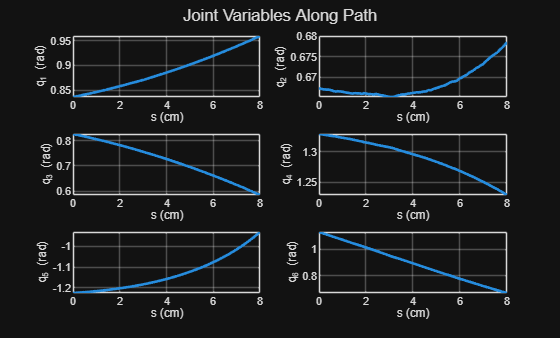

%% =========================================================
%  PLOT JOINT VARIABLES
%% =========================================================

figure;

for i = 1:6

    subplot(3,2,i)

    plot(spath,Q(:,i),'LineWidth',2)

    xlabel('s (cm)')
    ylabel(['q_' num2str(i) ' (rad)'])

    grid on

end

sgtitle('Joint Variables Along Path')
exportgraphics(gcf, 'figure1.pdf', ...
    'ContentType', 'vector');

%% =========================================================
%  CONSTRAINT FUNCTION
%% =========================================================

function F = trocarConstraint(X,Pp,Pt,Ps,r3,r5, r7)

xe = X(1);
ye = X(2);
ze = X(3);

xw = X(4);
yw = X(5);
zw = X(6);

lambda = X(7);

xp = Pp(1);
yp = Pp(2);
zp = Pp(3);

xt = Pt(1);
yt = Pt(2);
zt = Pt(3);

xs = Ps(1);
ys = Ps(2);
zs = Ps(3);

F(1) = lambda*xw + (1-lambda)*xe - xp;

F(2) = lambda*yw + (1-lambda)*ye - yp;

F(3) = lambda*zw + (1-lambda)*ze - zp;

F(4) = (xe-xw)^2 + (ye-yw)^2 + (ze-zw)^2 - r5^2;

F(5) = (xe-xs)^2 + (ye-ys)^2 + (ze-zs)^2 - r3^2;

F(6) = (xt-xw)^2 + (yt-yw)^2 + (zt-zw)^2 - r7^2;

F(7) = norm([xe-xp ye-yp ze-zp]) + ...
       norm([xw-xp yw-yp zw-zp]) - ...
       r3;

F = F(:);

end

%% =========================================================
%  HOMOGENEOUS TRANSFORMS
%% =========================================================

function T = trotz(q)

T = [cos(q) -sin(q) 0 0;
     sin(q)  cos(q) 0 0;
     0       0      1 0;
     0       0      0 1];
end

function T = troty(q)

T = [cos(q) 0 sin(q) 0;
     0      1 0      0;
    -sin(q) 0 cos(q) 0;
     0      0 0      1];
end

function T = transl(x,y,z)

T = [1 0 0 x;
     0 1 0 y;
     0 0 1 z;
     0 0 0 1];
end


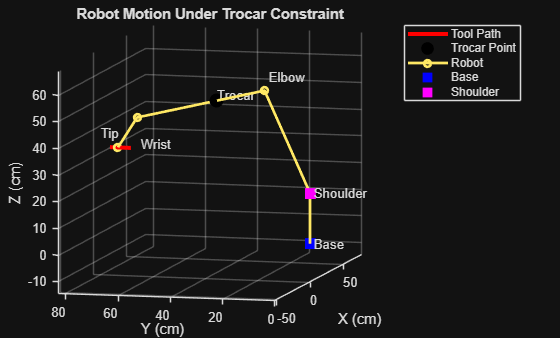

%% =========================================================
%  STATIC 3D PLOT
%% =========================================================

figure;
hold on;
grid on;
axis equal;
view(3);
view([-75.7 7.9])

xlabel('X (cm)');
ylabel('Y (cm)');
zlabel('Z (cm)');

title('Robot Motion Under Trocar Constraint');

% ---------------------------------------------------------
% Plot desired straight-line trajectory
% ---------------------------------------------------------

plot3(Pt(1,:),Pt(2,:),Pt(3,:),...
    'r','LineWidth',3);

% ---------------------------------------------------------
% Plot trocar point
% ---------------------------------------------------------

plot3(Pp(1),Pp(2),Pp(3),...
    'ko',...
    'MarkerFaceColor','k',...
    'MarkerSize',10);

text(Pp(1),Pp(2),Pp(3)+2,...
    'Trocar');

% ---------------------------------------------------------
% Plot robot configurations
% ---------------------------------------------------------

for k = 50

    % -----------------------------
    % Important points
    % -----------------------------

    Base     = [0;0;0];

    Shoulder = [0;0;r1];

    Elbow = Elbow_all(:,k);

    Wrist = Wrist_all(:,k);

    ToolTip = Pt(:,k);

    % -----------------------------------------------------
    % Draw robot links
    % -----------------------------------------------------

    Xrobot = [Base(1) Shoulder(1) Elbow(1) Wrist(1) ToolTip(1)];
    Yrobot = [Base(2) Shoulder(2) Elbow(2) Wrist(2) ToolTip(2)];
    Zrobot = [Base(3) Shoulder(3) Elbow(3) Wrist(3) ToolTip(3)];

    plot3(Xrobot,Yrobot,Zrobot,...
        '-o',...
        'LineWidth',2,...
        'MarkerSize',5);

    % -----------------------------------------------------
    % Draw trocar constraint line
    % (forearm passes through trocar)
    % -----------------------------------------------------

    % plot3([Elbow(1) Wrist(1)],...
    %       [Elbow(2) Wrist(2)],...
    %       [Elbow(3) Wrist(3)],...
    %       'g','LineWidth',3);

end

%% =========================================================
%  SHOW IMPORTANT POINTS CLEARLY
%% =========================================================

plot3(0,0,0,...
    'bs','MarkerSize',10,...
    'MarkerFaceColor','b');

plot3(0,0,r1,...
    'ms','MarkerSize',10,...
    'MarkerFaceColor','m');

text(0,0,0,' Base');
text(0,0,r1,' Shoulder');
text(Elbow(1),Elbow(2),Elbow(3)+5,' Elbow');
text(Wrist(1),Wrist(2),Wrist(3)-10,' Wrist');
text(ToolTip(1),ToolTip(2)+8,ToolTip(3)+5,' Tip');

legend('Tool Path','Trocar Point','Robot', 'Base', 'Shoulder');
exportgraphics(gcf, 'figure2.pdf', ...
    'ContentType', 'vector');

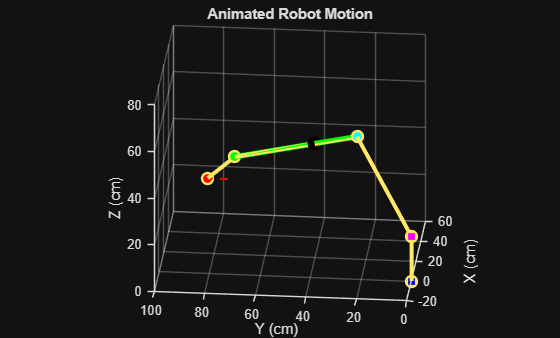

%% =========================================================
%  ANIMATION
%% =========================================================

figure;

for k = 1:N

    clf;

    hold on;
    grid on;
    axis equal;
    % view(3);
    view([-84.6 23.3]);

    xlabel('X (cm)');
    ylabel('Y (cm)');
    zlabel('Z (cm)');

    title('Animated Robot Motion');

    % -----------------------------------------------------
    % Axis limits
    % -----------------------------------------------------

    xlim([-20 60]);
    ylim([0 100]);
    zlim([0 80]);

    % -----------------------------------------------------
    % Plot full desired path
    % -----------------------------------------------------

    plot3(Pt(1,:),Pt(2,:),Pt(3,:),...
        'r--','LineWidth',1.5);

    % -----------------------------------------------------
    % Trocar point
    % -----------------------------------------------------

    plot3(Pp(1),Pp(2),Pp(3),...
        'ko',...
        'MarkerFaceColor','k',...
        'MarkerSize',10);

    % -----------------------------------------------------
    % Current robot points
    % -----------------------------------------------------

    Base     = [0;0;0];

    Shoulder = [0;0;r1];

    Elbow = Elbow_all(:,k);

    Wrist = Wrist_all(:,k);

    ToolTip = Pt(:,k);

    % -----------------------------------------------------
    % Robot structure
    % -----------------------------------------------------

    Xrobot = [Base(1) Shoulder(1) Elbow(1) Wrist(1) ToolTip(1)];
    Yrobot = [Base(2) Shoulder(2) Elbow(2) Wrist(2) ToolTip(2)];
    Zrobot = [Base(3) Shoulder(3) Elbow(3) Wrist(3) ToolTip(3)];

    plot3(Xrobot,Yrobot,Zrobot,...
        '-o',...
        'LineWidth',3,...
        'MarkerSize',7);

    % -----------------------------------------------------
    % Trocar constraint visualization
    % -----------------------------------------------------

    plot3([Elbow(1) Wrist(1)],...
          [Elbow(2) Wrist(2)],...
          [Elbow(3) Wrist(3)],...
          'g','LineWidth',4);

    % -----------------------------------------------------
    % Highlight important points
    % -----------------------------------------------------

    plot3(Base(1),Base(2),Base(3),...
        'bs','MarkerFaceColor','b');

    plot3(Shoulder(1),Shoulder(2),Shoulder(3),...
        'ms','MarkerFaceColor','m');

    plot3(Elbow(1),Elbow(2),Elbow(3),...
        'co','MarkerFaceColor','c');

    plot3(Wrist(1),Wrist(2),Wrist(3),...
        'go','MarkerFaceColor','g');

    plot3(ToolTip(1),ToolTip(2),ToolTip(3),...
        'ro','MarkerFaceColor','r');

    drawnow;

    pause(0.02);

end